load('WT_6_15jun22_mMac_Slice_Lng_green_with95CI.mat');
data_xes = xes; % same for all files
data_patchxes = patchxes; % same for all files
wt_mean = dataMean;
wt_ci = dataPatch;

load('Mylpfa_6_Slice_Lng_green_with95CI.mat')
mylpfb_mean = dataMean;
mylpfb_ci = dataPatch;



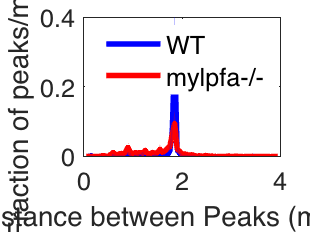

ax =   Axes with properties:

             XLim: [0 4]
             YLim: [0 0.3500]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties




% plot results
figure()
plot(data_xes, wt_mean, 'b', 'linewidth',3)
hold on
plot(data_xes, mylpfb_mean, 'r', 'linewidth',3)
%plot(data_xes, WTnoGFP_mean, 'k', 'linewidth',3)

patch(data_patchxes, wt_ci,'b', "FaceAlpha", 0.25, 'LineStyle', 'none')
patch(data_patchxes, mylpfb_ci, 'r', "FaceAlpha", 0.25, 'LineStyle', 'none')

%patch(data_patchxes, WTnoGFP_ci,'k', "FaceAlpha", 0.25, 'LineStyle', 'none')

xlabel('Distance between Peaks (micron)', 'FontSize', 14)
ylabel('Fraction of peaks/micron', 'FontSize',14)
xlim([0, 4])
%title('Title', 'FontSize', 16)

legend('WT', ...
    'mylpfa-/-', ...
    "FontSize", 14, "Location", 'NorthEast')
legend('boxoff')
ax = gca;
ax.FontSize = 14

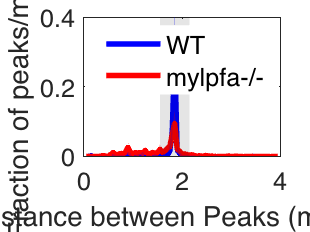

p1 =   Patch (data1) with properties:

    FaceColor: [0 0 0]
    FaceAlpha: 0.1000
    EdgeColor: [0 0 0]
    LineStyle: 'none'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  Show all properties


%X-Axis Shading

v1 = [1.75 0; 2.15 0; 2.15 0.4; 1.75 0.4];
f = [1 2 3 4];
p1= patch('Faces',f,'Vertices',v1,'FaceColor','black', 'facealpha', 0.1, 'LineStyle', 'none')

p1.Annotation.LegendInformation.IconDisplayStyle = 'off';

v2 = [0.6 0; 1.2 0; 1.2 0.4; 0.6 0.4];
f = [1 2 3 4];
p2= patch('Faces',f,'Vertices',v2,'FaceColor','black', 'facealpha', 0.1, 'LineStyle', 'none')
p2.Annotation.LegendInformation.IconDisplayStyle = 'off';

%v3 = [1.5 0; 3 0; 3 0.2; 1.5 0.2];
%f = [1 2 3 4];
%p3= patch('Faces',f,'Vertices',v1,'FaceColor','black', 'facealpha', 0.1, 'LineStyle', 'none')
%p3.Annotation.LegendInformation.IconDisplayStyle = 'off';

%v4 = [3 0; 4 0; 4 0.2; 3 0.2];
%f = [1 2 3 4];
%p4= patch('Faces',f,'Vertices',v1,'FaceColor','black', 'facealpha', 0.1, 'LineStyle', 'none')
%p4.Annotation.LegendInformation.IconDisplayStyle = 'off';
